# **Project:** How does the performance of a Greenpower car change during a race?

My team and I are going to use data from our performance at Goodwood race on 18/10/2026 to analyse how the performance of Empress (our car) changes during a race.

**Main objectives:**

- See what conclusions can be made about the performance of empress.

- Identify the source of what causes empress to slow down during race.

- Use the data to make the process of looking for solutions that allow empress to maintain speed for as long as possible during races easier.

Display Table:

GreenpowerRaceData_real_ = readtable('Greenpower Goodwood Race data.xlsx');

GreenpowerRaceData_real_

GreenpowerRaceData_real_ = 11×6 table
    LapNumber_1    LapTime_secs__1    LapNumber_2    LapTime_secs__2    TrackDistance_metres_    TotalRaceTime_mins_
    ___________    _______________    ___________    _______________    _____________________    ___________________

         1              341.5               1             343.4                 3860                      90        
         2              340.1               2             340.3                  NaN                     NaN        
         3              343.8               3             345.8                  NaN                     NaN        
         4              343.2               4             344.7                  NaN                     NaN        
         5              468.2               5          

Import data from table into variables:

lapNumber1 = GreenpowerRaceData_real_.LapNumber_1

lapNumber1 =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10
    11


lapTime1 = GreenpowerRaceData_real_.LapTime_secs__1

lapTime1 =   341.5000
  340.1000
  343.8000
  343.2000
  468.2000
  350.9000
  352.2000
  359.5000
  508.6000
  417.9000
  823.7000



lapNumber2 = GreenpowerRaceData_real_.LapNumber_2

lapNumber2 =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10
   NaN


lapTime2 = GreenpowerRaceData_real_.LapTime_secs__2

lapTime2 = 1.0e+03 *

    0.3434
    0.3403
    0.3458
    0.3447
    0.4721
    0.4877
    0.4525
    1.9558
    0.4093
    0.4026
       NaN



lapDistance = GreenpowerRaceData_real_.TrackDistance_metres_

lapDistance =         3860
         NaN
         NaN
         NaN
         NaN
         NaN
         NaN
         NaN
         NaN
         NaN
         NaN


totalRaceTime = GreenpowerRaceData_real_.TotalRaceTime_mins_

totalRaceTime =     90
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN


Calculate Average lap time:

avgLapTime1 = mean(lapTime1)

avgLapTime1 = 422.6909

avgLapTime2 = mean(lapTime2(1:10))

avgLapTime2 = 555.4200

Calculate Fastest lap:

fastestLap1 = min(lapTime1)

fastestLap1 = 340.1000

fastestLap2 = min(lapTime2(1:10))

fastestLap2 = 340.3000

Calculate Slowest lap:

slowestLap1 = max(lapTime1)

slowestLap1 = 823.7000

slowestLap2 = max(lapTime2(1:10))

slowestLap2 = 1.9558e+03

Calculate difference between fastest and slowest lap:

diff1 = slowestLap1 - fastestLap1

diff1 = 483.6000

diff2 = slowestLap2 - fastestLap2

diff2 = 1.6155e+03

Calculate the speed of each lap:

lapDistanceDivider = 3860; % metres

eachLapSpeed1 = lapDistanceDivider./lapTime1

eachLapSpeed1 =    11.3031
   11.3496
   11.2275
   11.2471
    8.2443
   11.0003
   10.9597
   10.7371
    7.5895
    9.2367
    4.6862


eachLapSpeed2 = lapDistanceDivider./lapTime2

eachLapSpeed2 =    11.2405
   11.3429
   11.1625
   11.1981
    8.1762
    7.9147
    8.5304
    1.9736
    9.4307
    9.5877
       NaN


Calculate Average lap speed:

avgLapSpeed1 = lapDistance(1)/avgLapTime1

avgLapSpeed1 = 9.1320

avgLapSpeed2 = lapDistance(1)/avgLapTime2 

avgLapSpeed2 = 6.9497

Graph to display the time taken for empress to complete each lap in Race 1:

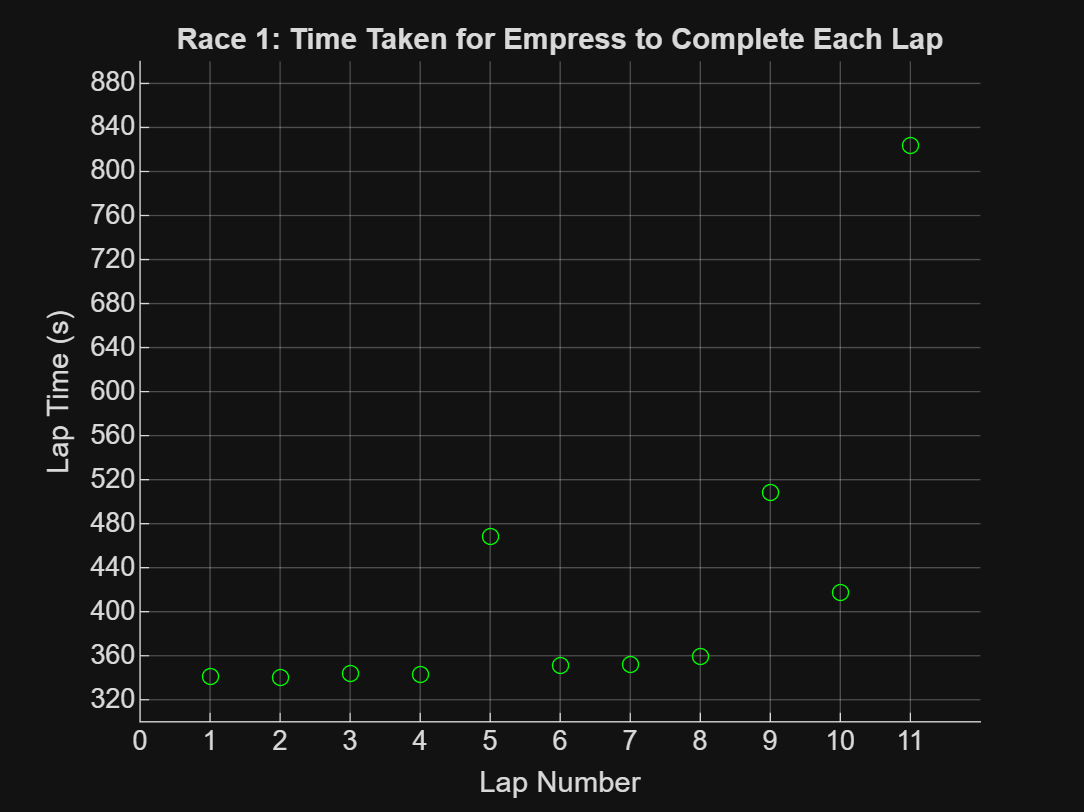

scatter(lapNumber1, lapTime1,"g", "o")
ylabel("Lap Time (s)")
xlabel("Lap Number")
title("Race 1: Time Taken for Empress to Complete Each Lap")
set(gca, "xtick", 0:1:11)
set(gca, "ytick", 0:40:900)
grid on

Graph to display the speed empress had each lap in Race 1:

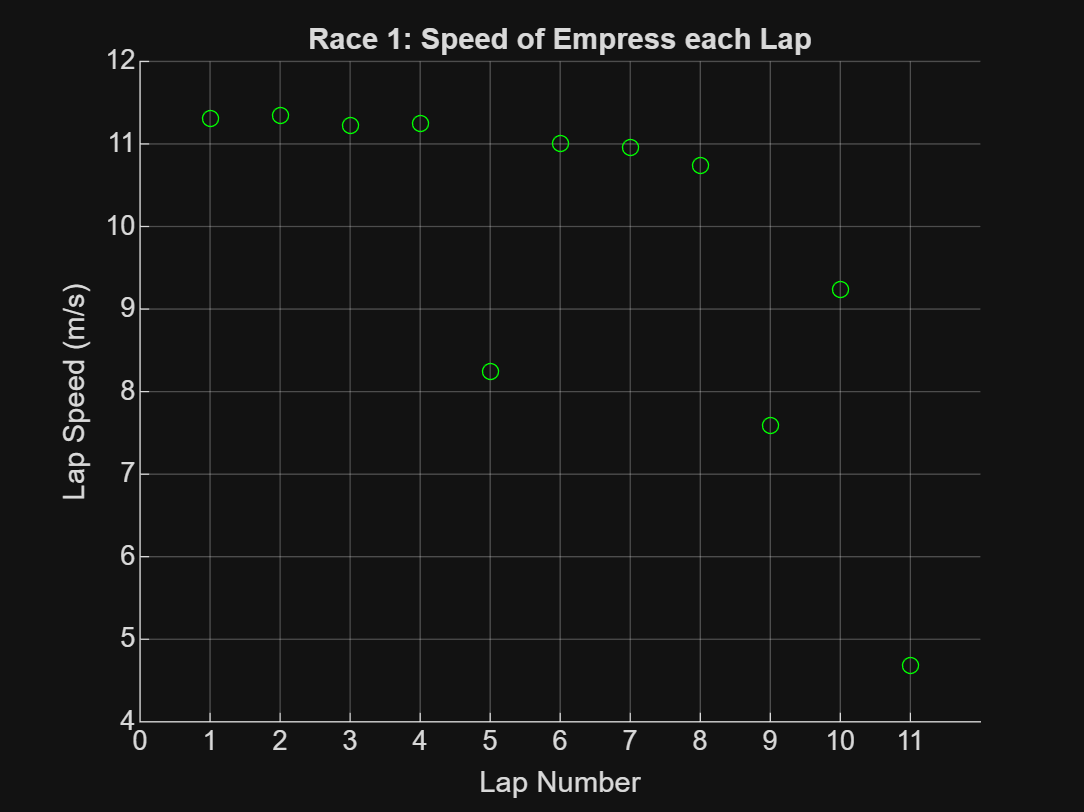

scatter(lapNumber1, eachLapSpeed1,"g", "o")
ylabel("Lap Speed (m/s)")
xlabel("Lap Number")
title("Race 1: Speed of Empress each Lap")
set(gca, "xtick", 0:1:11)
set(gca, "ytick", 0:1:15)
grid on

Graph to display the time taken for empress to complete each lap in Race 2:

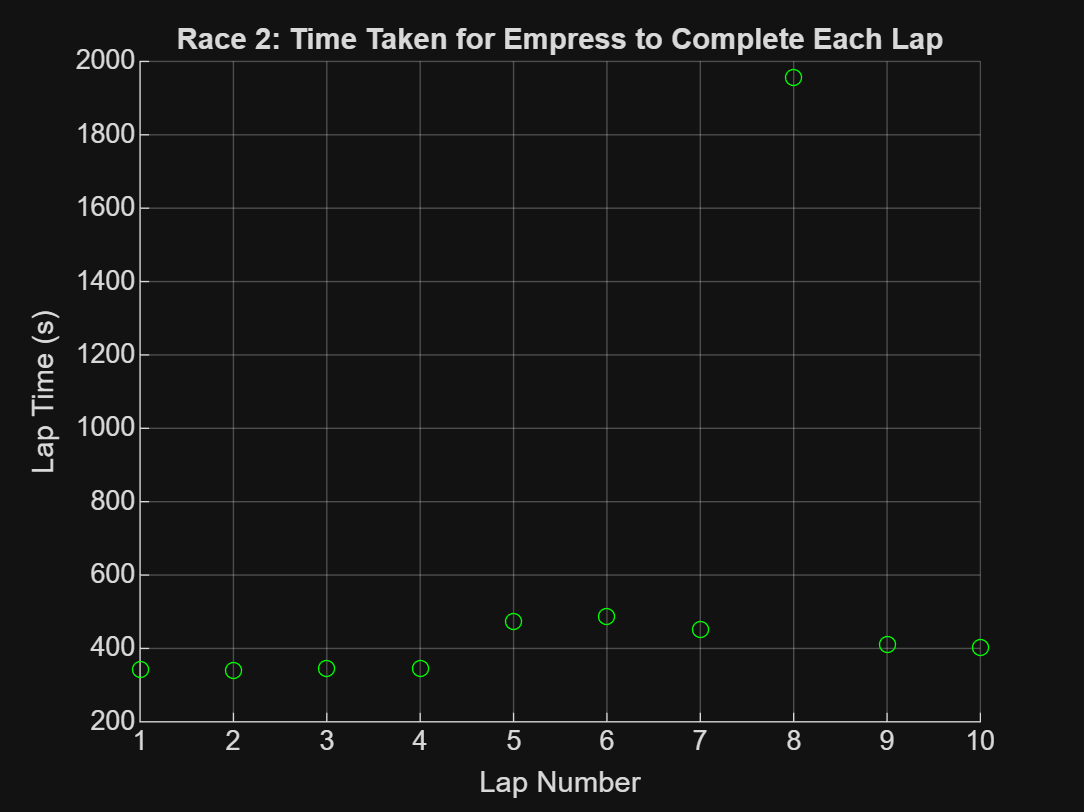

scatter(lapNumber2, lapTime2,"g", "o")
ylabel("Lap Time (s)")
xlabel("Lap Number")
title("Race 2: Time Taken for Empress to Complete Each Lap")
set(gca, "xtick", 0:1:10)
set(gca, "ytick", 0:200:2000)
grid on

Graph to display the speed empress had each lap in Race 2:

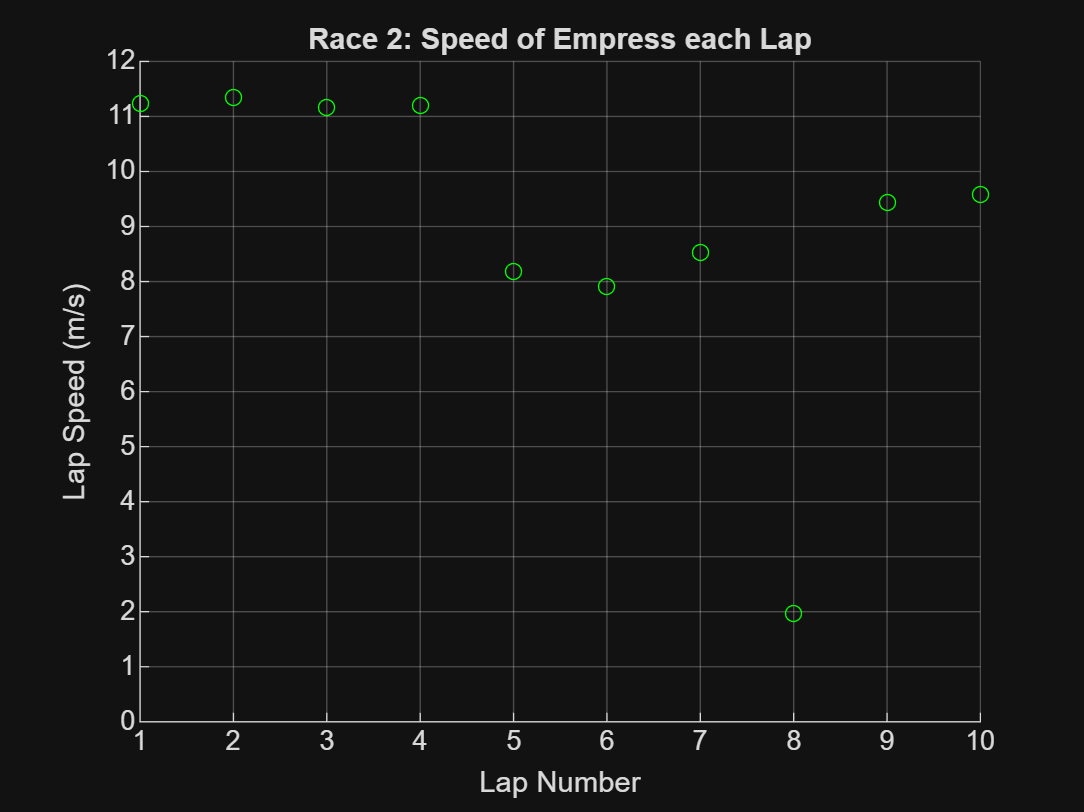

scatter(lapNumber2, eachLapSpeed2,"g", "o")
ylabel("Lap Speed (m/s)")
xlabel("Lap Number")
title("Race 2: Speed of Empress each Lap")
set(gca, "xtick", 0:1:10)
set(gca, "ytick", 0:1:15)
grid on

Graph to display the percentage change in Lap time from Lap One in Race 1 and 2:

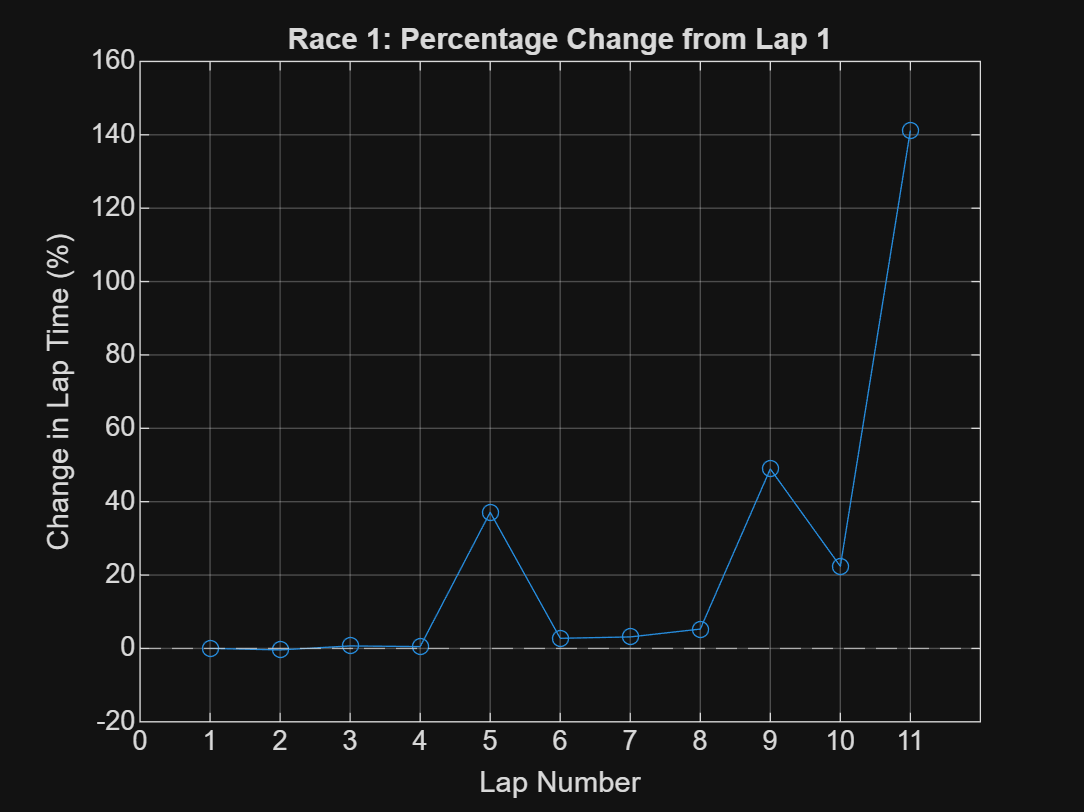

percentageChange1 = ((lapTime1 - lapTime1(1)) ./ lapTime1(1)) * 100;

percentageChange2 = ((lapTime2 - lapTime2(1)) ./ lapTime2(1)) * 100;

figure
plot(lapNumber1, percentageChange1, '-o')
xlabel('Lap Number')
ylabel('Change in Lap Time (%)')
title('Race 1: Percentage Change from Lap 1')
set(gca, "xtick", 0:1:11)
set(gca, "ytick", -20:20:160)
yline(0, '--')
grid on

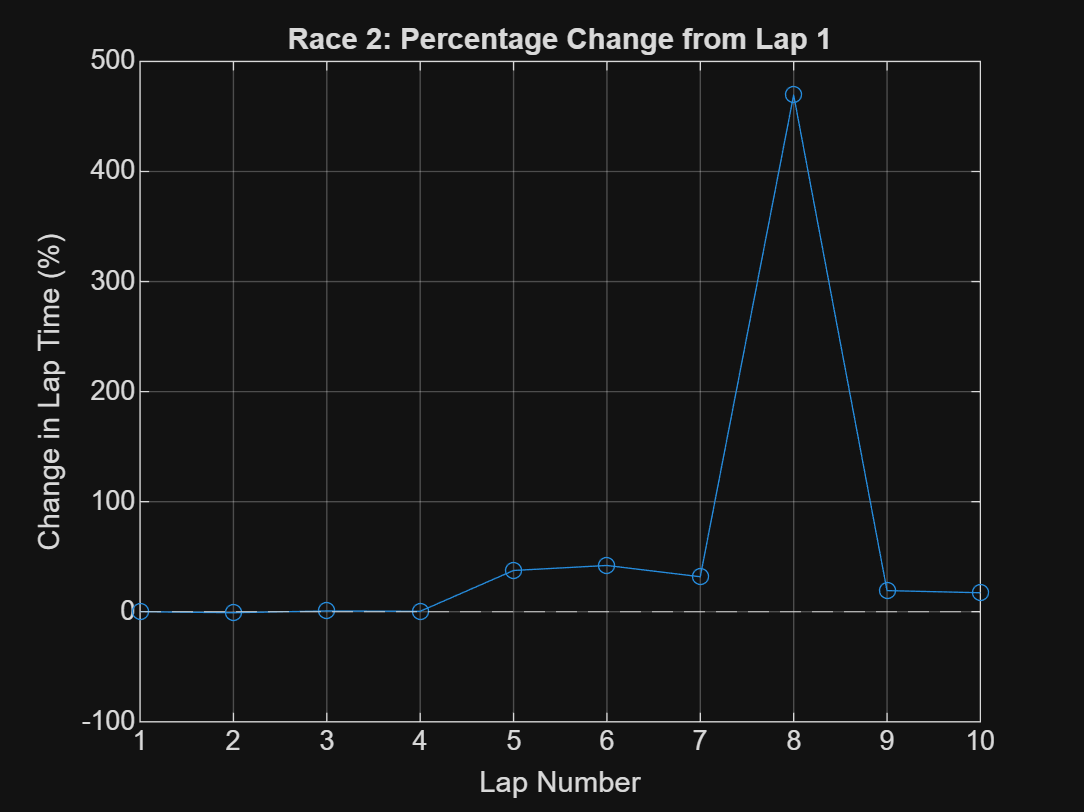


figure
plot(lapNumber2, percentageChange2, '-o')
xlabel('Lap Number')
ylabel('Change in Lap Time (%)')
title('Race 2: Percentage Change from Lap 1')
set(gca, "xtick", 0:1:10)
set(gca, "ytick", -100:100:500)
yline(0, '--')
grid on

### **Empress' place in each race:**

Race 1: 30th

Race 2: Disqualified (we asked to be disqualified so we could change batteries and send Nate out)

### **Analysis of graphs:**

**Race 1:**

**Conclusions from Graph titled "Race 1: Time Taken for Empress to Complete Each Lap":**

The time taken for the car to complete each lap is quite steady around 340 seconds to 360 seconds (despite an anomaly on lap 5 of around 468 seconds, which is likely from a pit change) until lap 9 out of 11 where it jumps to around 509 seconds, drops slightly on lap 10 to 418 seconds, and then spikes to 824 seconds on lap 11. This final lap is well over double the initial time taken. 

Therefore, Empress' performance declined significantly toward the end of the race. The time taken was quite consistent in the first section (laps 1 to 8), but in the final three laps it became erratic and increased sharply as the batteries ran flat around the 45-minute mark.

**Conclusions from Graph titled "Race 1: Speed of Empress each Lap":**

The speed of the car is quite constant between 10.7 m/s and 11.3 m/s (despite a dip on lap 5 to around 8.2 m/s from a likely pit change) until lap 9 out of 11 where it drops to around 7.6 m/s, recovers slightly to 9.2 m/s on lap 10, and then falls to about 4.7 m/s on lap 11. This final speed is less than half the initial speed.

One area of note is the sharp drop-off in speed during the final three laps rather than a gradual decline across the whole race. Because the 40Amp batteries died at roughly 45 minutes instead of lasting the full 90-minute race, the car lost power rapidly at the end. Using an eChook (data logging tool to log current, voltage etc.) during races could help determine why the battery drained so quickly.

Empress' performance declined. The speed was quite consistent in the first section, but in the final laps it decreased sharply.

**Conclusions from Graph titled "Race 1: Percentage Change from Lap 1":**

The percentage change in lap time remains quite consistent around 0% to 5% for the first 4 laps and laps 6 to 8, despite a spike of around 37% on lap 5, which is likely due to a pit change. On lap 9 out of 11, the percentage change increases sharply to around 49%, drops to 22% on lap 10, and then rises significantly to 141% on lap 11. This means the final lap took more than twice as long as lap 1.

Therefore, Empress maintained a relatively consistent performance for most of the first 8 laps, apart from lap 5. However, performance declined significantly towards the end of the race, particularly in the final three laps. This supports the team's observations that the batteries were struggling towards the end of the race, although further investigation is needed to confirm the cause.

**Race 2:**

**Conclusions from Graph titled "Race 2: Time Taken for Empress to Complete Each Lap":**

The time taken for the car to complete each lap is quite steady around 340 seconds to 346 seconds until lap 5 out of 10, where it jumps to around 472 seconds and stays between 452 seconds and 488 seconds through lap 7. On lap 8, there is a massive anomaly where the lap time spikes to 1956 seconds (over 32 minutes), likely due to a red flag stoppage or an extended pit change. For laps 9 and 10, the time settles around 403 to 409 seconds, which is still noticeably higher than the initial time taken.

Therefore, Empress' performance declined and was heavily disrupted by a major stoppage on lap 8, splitting the consistent lap times into two different sections (laps 1 - 4 and laps 5 - 7/9 - 10).

**Conclusions from Graph titled "Race 2: Speed of Empress each Lap":**

The speed of the car is quite constant around 11.1 m/s to 11.3 m/s until lap 5 out of 10 where it drops to between 7.9 m/s and 8.5 m/s for laps 5 to 7. On lap 8, the speed drops to an anomaly of around 2.0 m/s (corresponding to the 1956 second lap time). On laps 9 and 10, the speed recovers slightly to around 9.4 m/s to 9.6 m/s, which is still lower compared to the initial speed.

Therefore, Empress' performance declined and was inconsistent compared to the start of the race, ending early at 10 laps before finishing the full race distance.

**Conclusions from Graph titled "Race 2: Percentage Change from Lap 1":**

The percentage change in lap time remains close to 0% for the first 4 laps, showing that Empress maintained a consistent performance at the start of the race. However, on lap 5 out of 10, the percentage change jumps to around 37%, increases slightly to 42% on lap 6, and then drops to around 32% on lap 7. On lap 8, there is a massive anomaly where the percentage change reaches approximately 470%, corresponding to the lap time of over 32 minutes. The percentage change then drops to around 19% on lap 9 and 17% on lap 10.

Therefore, Empress' performance declined much earlier in Race 2 compared to Race 1. Unlike Race 1, where lap times returned close to their initial values after lap 5, Race 2 continued to have noticeably longer lap times from lap 5 onwards. This could suggest that something happened during the pit stop which affected the car's performance. However, the reason for the unusually long lap 8 and the possible electrical issues still need to be investigated.

### **Overall analysis:**

**Which race did Empress have a better performance in and why?**

Empress performed better in Race 1.

In Race 1, Empress completed 11 laps and placed 30th, maintaining a consistent speed of around 10.7 - 11.3 m/s for 7 of the first 8 laps. 

In Race 2, the speed dropped much earlier (by lap 5), suffered a massive 32-minute delay on lap 8, only completed 10 laps, and resulted in a disqualification.

Furthermore, because the average lap speed across the whole 90-minute window is skewed by the car stopping early at around 45 minutes with flat batteries, looking at the individual lap consistency shows Race 1 was much smoother.

Comparing both Percentage Change from Lap 1 graphs, Empress maintained a more consistent performance in Race 1, with most of the first 8 laps remaining close to the initial lap time. In Race 2, performance declined earlier and remained less consistent after lap 5.

One area of note is that both races show a noticeable increase in lap time on lap 5, suggesting that pit stops may have affected performance. However, Race 1 recovered almost immediately, while Race 2 continued to show slower lap times. This makes it worth investigating whether the electrical system, particularly the porterbox or wiring, could have contributed to the differences in performance between the two races.

**What was the cause of reduction in speed in both races?**

Based on the team's post-race notes, the main cause of the reduction in speed and early retirement in both races was massive battery management issues, where the 40Amp batteries lasted only about 45 minutes instead of the full 90-minute race duration. The team suspects this rapid battery drain was caused by high current draw from rust in the motor or an issue with the electrics/porter box. 

Additionally, as noted in previous race reflections, the car's overall speed is also limited by its heavy chassis (from excess resin) and aerodynamics, which puts extra load on the motor and drains the batteries faster.

### **Next steps:**

After consulting with the team, here are some next steps we would like to move forward with. 

- Strip and test the electrics: Remove the electrical components from Empress to test the motor and porter box, checking specifically for rust in the motor that may be causing excessive resistance and draining the 40Amp batteries in 45 minutes.

- Investigate the porterbox: Discuss with Mr Bamford whether the porterbox could be contributing to the battery draining quickly, particularly when entering and leaving the pits. Although the porterbox is considered fairly robust, it has previously required resoldering and silicone repairs, suggesting there may be an electrical fault. Ask Mr Bamford (Head of Greenpower Club) for his opinion on whether the porterbox should be tested or replaced, as replacing it may be a relatively inexpensive solution.

- Ask Mr Bamford as a team for some of his time to analyse this information and look to possible reasons as we are quite sure something is going wrong in the electrics. We would like to suggest a complete rewire since it’s unlikely to be the motor (we have tried 2 now).

- Data logging: Fit or check the eChook data logger before the next season so we can monitor voltage and current draw in real time and catch battery drain before the car dies on track.

Export code and results as a pdf

export("Goodwood_2026_empress.mlx")

ans = '/MATLAB Drive/Goodwood_2026_empress.pdf'